%Sends a simple cosine wave to the DAC


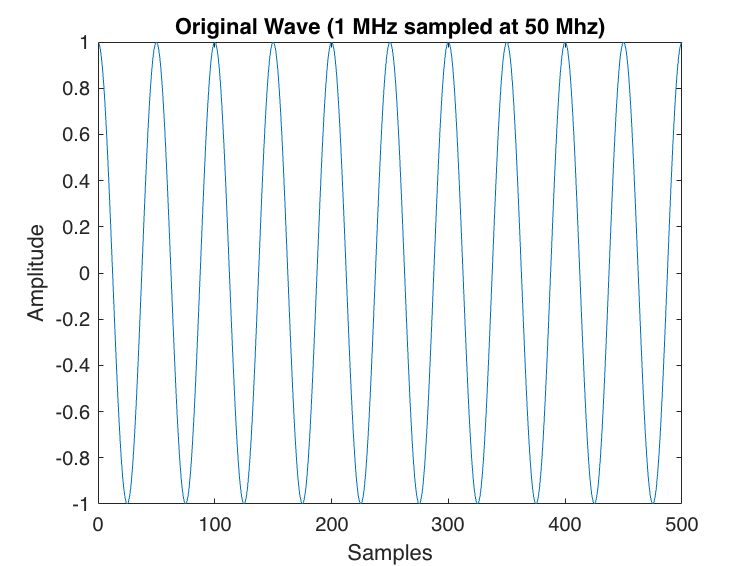

samples = 1:500;

fs = 50e6; %Hz
f = 1e6; %Hz;

wave = cos(2*pi*(f/fs)*samples);
wave = wave';

plot(wave(1:500))
title("Original Wave (1 MHz sampled at 50 Mhz)")
ylabel("Amplitude")
xlabel("Samples")


txScaledWave = (wave/2) + 0.5;

toDAC_simple = round(txScaledWave .* 255);

freq_shft = fftshift((-0.5:1/500:0.5-1/500)*50e6);

[H1, ~] = freqz(wave,1,500,'whole');

file_name = "toDAC_simple.csv";
writematrix(toDAC_simple, file_name);


fromADC = ((readmatrix('ADCout_simple3.csv') / 255) - 0.5) * 2;
[H2, ~] = freqz(fromADC(:,1), 1, 500, 'whole');


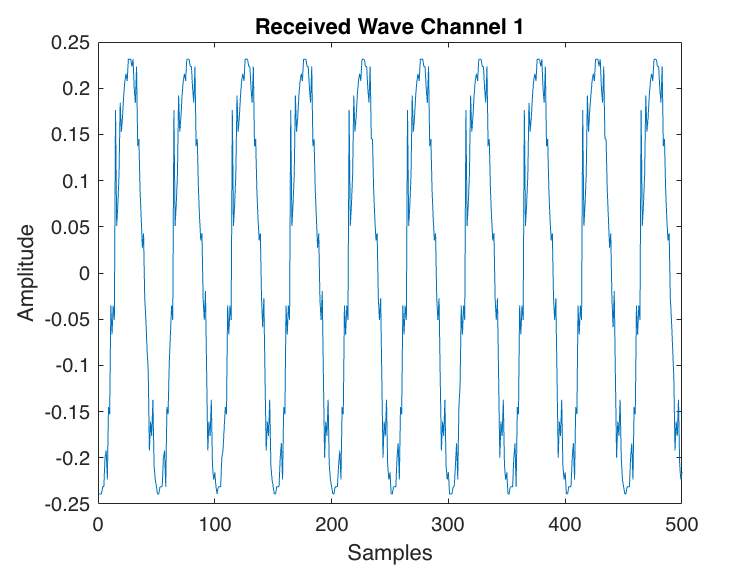

clf
plot(fromADC(:,1))
title("Received Wave Channel 1")
ylabel("Amplitude")
xlabel("Samples")

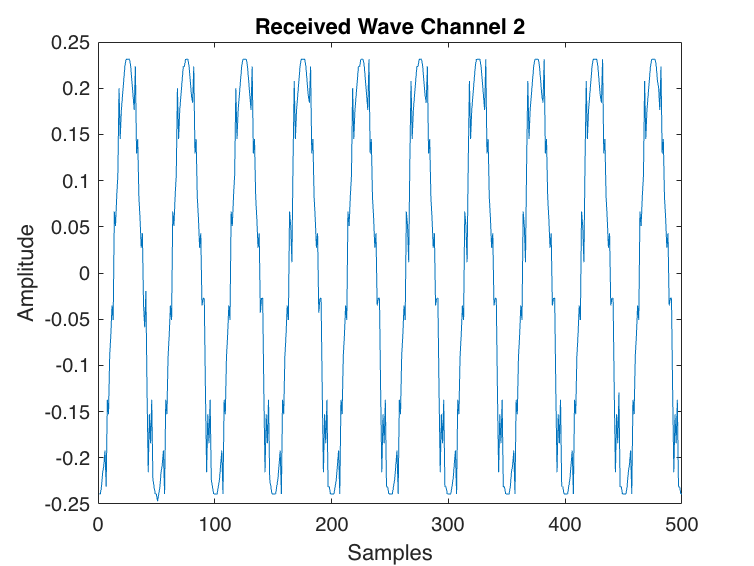

plot(fromADC(:,2))
title("Received Wave Channel 2")
ylabel("Amplitude")
xlabel("Samples")

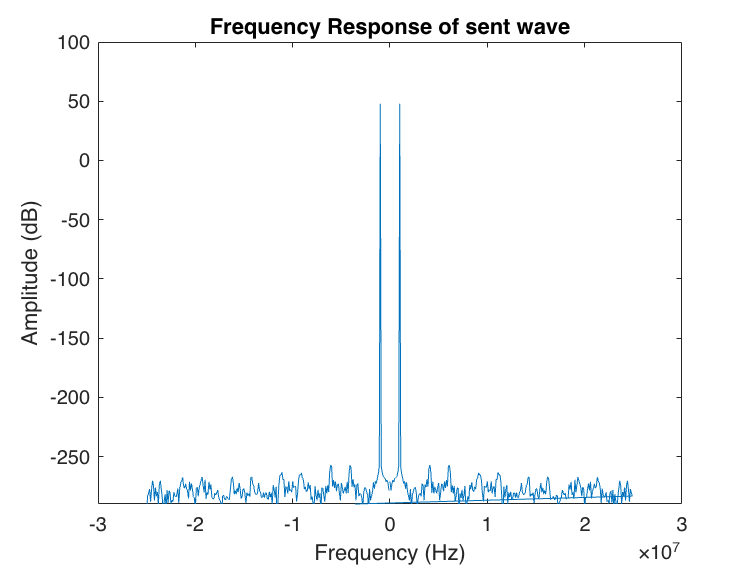

plot(freq_shft, mag2db(abs(H1)))
title("Frequency Response of sent wave")
xlabel("Frequency (Hz)")
ylabel("Amplitude (dB)")
ylim([-290, 100])

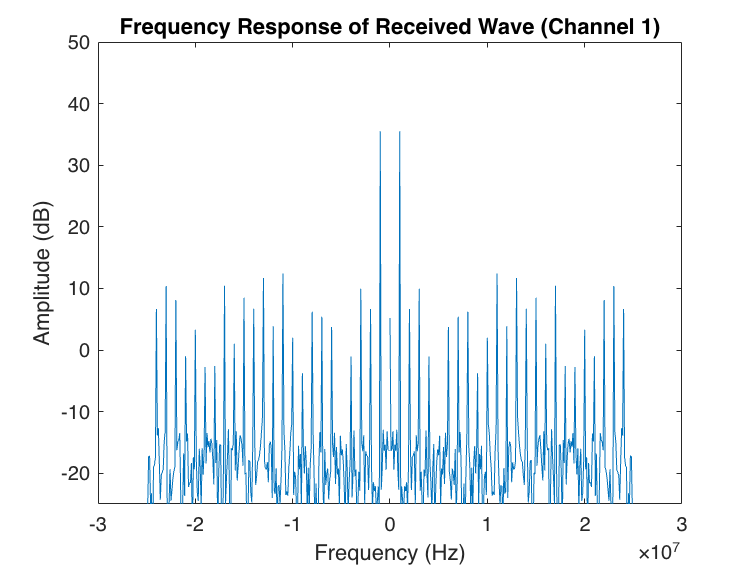

clf
H2(251) = [];
freq_shft(251)=[];
plot(freq_shft, mag2db(abs(H2)))
title("Frequency Response of Received Wave (Channel 1)")
xlabel("Frequency (Hz)")
ylabel("Amplitude (dB)")
ylim([-25, 50])